% divide 5*10 grids for data from simulation
freqsimu=ones(5,10,35);
i=1;
while i<1001
    if mu_trans(i)==0.5
        indexmu=5;
    else
        indexmu=ceil((mu_trans(i)-0.25)/0.05+0.0000001);
    end
    if rejection_of_factions(i)==0.5
        indexre=10;
    else
        indexre=ceil(rejection_of_factions(i)/0.05+0.0000001);
    end
    freqsimu(indexmu,indexre,sum(freqsimu(indexmu,indexre,:)~=1)+1)=op_trans(i);
    i=i+1;
end

未定义与 'double' 类型的输入参数相对应的函数 'mu_trans'。


% generate data through the probability distribution
loc=[];
mu=0.25;
while mu<=0.50001
    op=0;
    while op<=0.50001
        re=0;
        while re<=0.50001 
            A1=0.5^2-re^2;
            A2=re^0.5;
            m1=-(0.0004*exp(12*mu))+0.1614;
            m2=(0.003*exp(8*mu)+0.125)*(0.68*re+1);
            sigma1=(0.06*mu-0.005)/(1+exp(100*(re-(1.4*mu-0.25))));
            sigma2=(-0.02*mu+0.02)/(1+exp(100*(-re+(1.8*mu-0.425))));
            prob=(A1*sigma1/sqrt(2*pi)*exp(-((op-m1)^2/2/sigma1^2))+A2*sigma2/sqrt(2*pi)*exp(-((op-m2)^2/2/sigma2^2)))/(A1+A2);
            if rand()<prob 
                loc=[loc;[mu,re,op]];
            end
            re=re+0.0025;
        end
        op=op+0.0025;
    end
    mu=mu+0.00125;
end

% decrease the density of generated data and make it consistent with the data from simulation
n=length(loc);
i=1;
while i<n-999 % 999 should be replaced to your data scale submit 1, here our data scale is 1000
    j=randi(n-i+1);
    loc(j,:)=[];
    i=i+1;
end

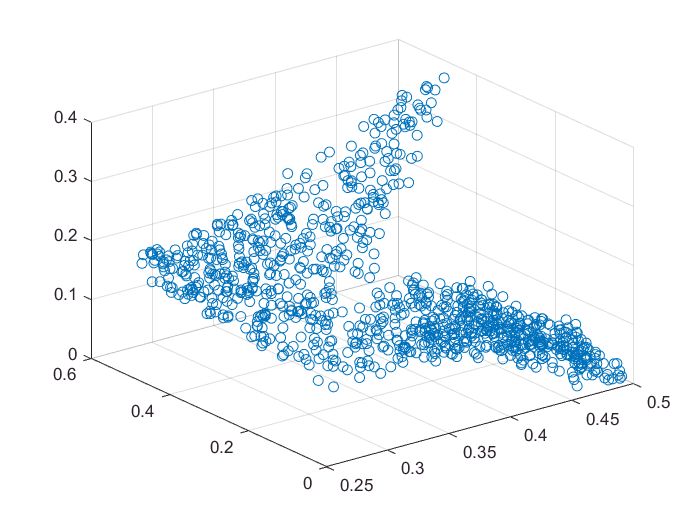

% draw diagrams for generated data
scatter3(loc(:,1),loc(:,2),loc(:,3))

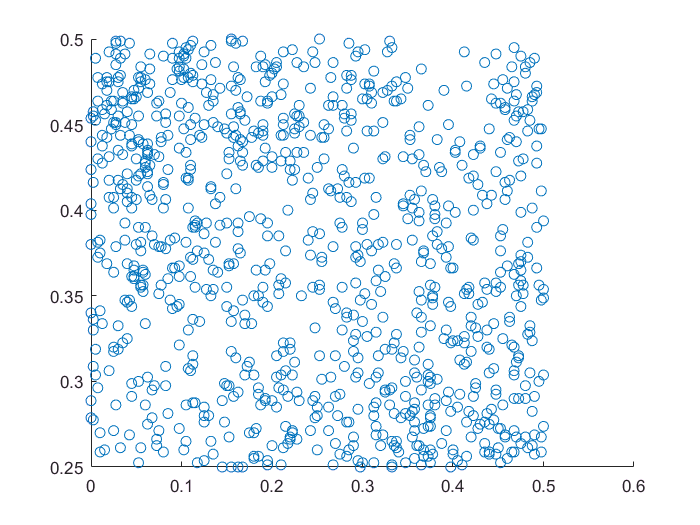

scatter(loc(:,2),loc(:,1))

% divide grids to 5*10 for data generated by our formula
n=length(loc);
freqpro=ones(5,10,ceil(n/50)*3);
i=1;
while i<n+1
    if abs(loc(i,1)-0.5)<0.0000001
        indexmu=5;
    else
        indexmu=ceil((loc(i,1)-0.25)/0.05+0.0000001);
    end
    if abs(0.5-loc(i,2))<0.0000001
        indexre=10;
    else
        indexre=ceil(loc(i,2)/0.05+0.0000001);
    end
    freqpro(indexmu,indexre,sum(freqpro(indexmu,indexre,:)~=1)+1)=loc(i,3);
    i=i+1;
end

% ks test
len_op=size(freqpro,3);
matrix_h=zeros(5,10);
matrix_p=zeros(5,10);
for indexmu=1:5
    for indexre=1:10
        simudata=reshape(freqsimu(indexmu,indexre,:),[35 1]);
        simudata=simudata(simudata~=1);
        prodata=reshape(freqpro(indexmu,indexre,:),[len_op 1]);
        prodata=prodata(prodata~=1);
        [h,p]=kstest2(simudata,prodata);
        matrix_h(indexmu,indexre)=h;
        matrix_p(indexmu,indexre)=p;
    end
end
1-sum(sum(matrix_h))/50

ans = 0.8600

% what percentage of grids have passed the k-s test
percentage=[percentage 1-sum(sum(matrix_h))/50];